## Section 1. Variables and parameters

clear

fprintf("\n\n\n")

fprintf("------------------------------------------------");

------------------------------------------------

fprintf("------------------- SECTION 1 ------------------");

------------------- SECTION 1 ------------------


% laser wavelength
lambda = 632.8*10^-9; % m

% distance between aperture and screen
d = 20*10^-3;

% aperture radius
Aperture_Radius = (0.9/2)*10^-3; % m

% pixel width
pixel_width = 94.8*10^-6; % m

% screen size
Screen_Size = 1000*pixel_width; % m

% aperture area
Aperture_Area = pi*(Aperture_Radius)^2; % m^2

% wavenumber
k = 2*pi/lambda;

% Initial intensity
I_0 = 1;

fprintf("lambda = %d m", lambda);

lambda = 6.328000e-07 m

fprintf("d = %d m", d);

d = 2.000000e-02 m

fprintf("Aperture_Radius = %d m", Aperture_Radius);

Aperture_Radius = 4.500000e-04 m

fprintf("pixel_width = %d m", pixel_width);

pixel_width = 4.800000e-06 m

fprintf("Screen_Size = %d m", Screen_Size);

Screen_Size = 4.800000e-03 m

fprintf("Aperture_Area = %d m^2", lambda);

Aperture_Area = 6.328000e-07 m^2

fprintf("k = %d", k);

k = 9.929180e+06

fprintf("I_0 = %d", I_0);

I_0 = 1

fprintf("------------------------------------------------");

------------------------------------------------

## Section 2. Dividing aperture into area elements

fprintf("\n\n\n")

fprintf("------------------------------------------------");

------------------------------------------------

fprintf("------------------- SECTION 2 ------------------");

------------------- SECTION 2 ------------------


% Calculate the initial value dxa for the spacing between aperture elements
d_a = Aperture_Radius;
d_s = 1/2*Screen_Size;
dxa = lambda/(2*(d_s + d_a)) * sqrt((d_s + d_a)^2 + d^2); % m

% For large distances between the apperture and the target, the distance
% dxa might be comparable, or even larger than the aperture size. Here I
% check if the initial distance is large and limit it to 0.1 mm
if dxa > 0.1e-3
    dxa = 0.1e-3;
end

%If you want to make dxa smaller, then you can uncomment next line and use it.
%dxa=dxa/10;

N_a = ceil(Aperture_Radius/dxa); % Number of  elements that fits along the aperture radius;
Xa = -N_a*dxa:dxa:N_a*dxa; % Vector that contains the x coordinates of elements

[XaM, YaM] = meshgrid(Xa,Xa); % Matrix XaM contains X coordinates of all elements;
                              % Matrix YaM contains Y coordinates of all elements;

fprintf("d_a = %d m", d_a);

d_a = 4.500000e-04 m

fprintf("d_s = %d m", d_s);

d_s = 2.400000e-03 m

fprintf("dxa = %d m", dxa);

dxa = 2.242781e-06 m

fprintf("N_a = %d", N_a);

N_a = 201

fprintf("XaM =");

XaM =

disp(XaM);

   1.0e-03 *

  Columns 1 through 16

   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4172
   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4172
   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4172
   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4172
   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4172
   -0.4508   -0.4486   -0.4463   -0.4441   -0.4418   -0.4396   -0.4373   -0.4351   -0.4329   -0.4306   -0.4284   -0.4261   -0.4239   -0.4216   -0.4194   -0.4

fprintf("YaM =");

YaM =

disp(YaM);

   1.0e-03 *

  Columns 1 through 16

   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508   -0.4508
   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486   -0.4486
   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463   -0.4463
   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441   -0.4441
   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418   -0.4418
   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4396   -0.4

fprintf("------------------------------------------------");

------------------------------------------------

## Section 3. Initializing the amplitude of the wave A(r_0) at the aperture

fprintf("\n\n\n")

fprintf("------------------------------------------------");

------------------------------------------------

fprintf("------------------- SECTION 3 ------------------");

------------------- SECTION 3 ------------------

% Create a 2D array of amplitudes of the same size as arrays XaM and YaM of x and y coordinates
% All values are set to 0
A0 = zeros(size(XaM));

% Calculate the amplitude of the wave here:
P_a = 1; % W
Screen_Area = (1000*4.8*10^-6) * (1000*4.8*10^-6); % m^2
A_0 = sqrt(P_a/Screen_Area); % W/m^2

% 2D array that contains distances from corresponding elements to the
% center of the aperture;
Ra = sqrt(XaM.^2+YaM.^2);

% 2D logical array. Element of this array is equal to 1 (true) ff distance of the corresponding 
% aperture element to the center of the aperture is less than the aperture radius (element belongs to the aperture).
ind = (Ra<=Aperture_Radius);

% Setting amplitudes of all elements that are inside the aperture to the
% initial value
A0(ind) = A_0;

fprintf("P_a = %d W", P_a);

P_a = 1 W

fprintf("Screen_Area = %d m^2", Screen_Area);

Screen_Area = 2.304000e-05 m^2

fprintf("A_0 = %d", A_0);

A_0 = 2.083333e+02

fprintf("Ra =");

Ra =

disp(Ra);

   1.0e-03 *

  Columns 1 through 16

    0.6375    0.6359    0.6344    0.6328    0.6312    0.6296    0.6281    0.6265    0.6250    0.6234    0.6219    0.6203    0.6188    0.6173    0.6157    0.6142
    0.6359    0.6344    0.6328    0.6312    0.6296    0.6280    0.6265    0.6249    0.6234    0.6218    0.6202    0.6187    0.6172    0.6156    0.6141    0.6126
    0.6344    0.6328    0.6312    0.6296    0.6280    0.6264    0.6249    0.6233    0.6217    0.6202    0.6186    0.6171    0.6155    0.6140    0.6124    0.6109
    0.6328    0.6312    0.6296    0.6280    0.6264    0.6248    0.6233    0.6217    0.6201    0.6186    0.6170    0.6155    0.6139    0.6124    0.6108    0.6093
    0.6312    0.6296    0.6280    0.6264    0.6248    0.6233    0.6217    0.6201    0.6185    0.6170    0.6154    0.6138    0.6123    0.6107    0.6092    0.6076
    0.6296    0.6280    0.6264    0.6248    0.6233    0.6217    0.6201    0.6185    0.6169    0.6154    0.6138    0.6122    0.6107    0.6091    0.6076    0.6

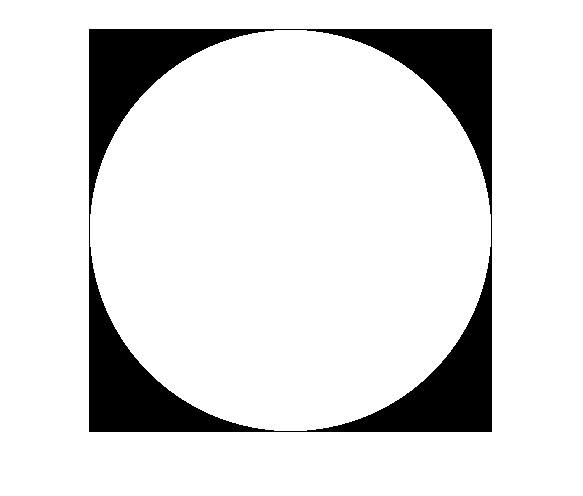

figure(1);
imshow(A0./max(A0(:)));

fprintf("------------------------------------------------");

------------------------------------------------

## Section 4. Dividing screen into area elements

fprintf("\n\n\n")

fprintf("------------------------------------------------");

------------------------------------------------

fprintf("------------------- SECTION 4 ------------------");

------------------- SECTION 4 ------------------


% Calculate the initial value dxs for the spacing between screen elements elements
dxs = lambda/(2*(d_s + d_a)) * sqrt((d_s + d_a)^2 + d^2); % m
dxs = dxs;

% Use what you have learned in Section 2 and create here a 1D array that contains x coordinated 
% of elements
N_s = ceil(d_s/dxs); % Number of  elements that fits along the aperture radius;
Xs = -N_s*dxs:dxs:N_s*dxs; % Vector that contains the x coordinates of elements


fprintf("dxs = %d m", dxs);

dxs = 2.242781e-06 m

fprintf("N_s = %d", N_s);

N_s = 1071

fprintf("Xs =");

Xs =

disp(Xs);

  Columns 1 through 16

   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024

  Columns 17 through 32

   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0024   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023

  Columns 33 through 48

   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023

  Columns 49 through 64

   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023   -0.0023

  Columns 65 through 80

   -0.0023   -0.0023   -0.0023   -0.0023   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022   -0.0022

  Columns 81 through 96

   -0.0022   -0.0022   -0.0022   -0.0022 

fprintf("------------------------------------------------");

------------------------------------------------

## Section 5. Constructing diffraction pattern

fprintf("\n\n\n")

fprintf("------------------------------------------------");

------------------------------------------------

fprintf("------------------- SECTION 5 ------------------");

------------------- SECTION 5 ------------------


% This section is the main body of the simulation. In this section you have to:
% 1) Calculate the complex amplitude A(r) of the wave and its intensity I_wave(r) for every element of the array of screen elements Xs;
    A = zeros(size(Xs));
    
    for i = 1:length(Xs)
        r_minus_r_a = sqrt((XaM - Xs(i)).^2 + (YaM - 0).^2 + d.^2);
        theta = acos(d./r_minus_r_a);
        K = -1i/(2*lambda).*(1+cos(theta));
        allAmps_x = imag(A0.*K.*exp(1i.*k.*abs(r_minus_r_a))./abs(r_minus_r_a).*dxs^2);
        allAmps_x(isinf(allAmps_x) | -isinf(allAmps_x)) = 0;
        A(i) = sum(sum(allAmps_x));
    end
    
    I_wave = A.^2;
    
    fprintf("A = ");

A = 

    disp(A);

  Columns 1 through 16

   -2.9496    1.6751    0.1006   -1.2114    1.1029   -0.1942   -0.6004    0.7224   -0.4130    0.3687   -0.9693    1.8413   -2.1918    1.6047   -0.5214   -0.0988

  Columns 17 through 32

   -0.3403    1.4748   -2.2634    1.9262   -0.6748   -0.4653    0.5908    0.2597   -1.1784    1.2722   -0.4983   -0.3534    0.4829    0.1394   -0.8184    0.9291

  Columns 33 through 48

   -0.5946    0.5092   -1.0888    1.8928   -2.0120    1.0793    0.1892   -0.6055   -0.2523    1.4650   -1.5719    0.0447    2.0595   -3.0207    2.1084   -0.3064

  Columns 49 through 64

   -0.6595    0.0230    1.3334   -1.8965    1.1421   -0.0253   -0.1554   -0.7714    1.6922   -1.5321    0.5328    0.0122    0.6992   -1.9403    2.1978   -0.9202

  Columns 65 through 80

   -0.7411    1.1494   -0.0498   -1.0734    0.6509    1.1421   -2.5222    2.1254   -0.6126   -0.0588   -1.0720    2.7734   -2.9818    1.2001    0.8687   -1.2374

  Columns 81 through 96

   -0.1097    1.2605   -0.6507   -1.1310 

    fprintf("I_wave = ");

I_wave = 

    disp(I_wave);

   1.0e+04 *

  Columns 1 through 16

    0.0009    0.0003    0.0000    0.0001    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0003    0.0005    0.0003    0.0000    0.0000

  Columns 17 through 32

    0.0000    0.0002    0.0005    0.0004    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001

  Columns 33 through 48

    0.0000    0.0000    0.0001    0.0004    0.0004    0.0001    0.0000    0.0000    0.0000    0.0002    0.0002    0.0000    0.0004    0.0009    0.0004    0.0000

  Columns 49 through 64

    0.0000    0.0000    0.0002    0.0004    0.0001    0.0000    0.0000    0.0001    0.0003    0.0002    0.0000    0.0000    0.0000    0.0004    0.0005    0.0001

  Columns 65 through 80

    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0006    0.0005    0.0000    0.0000    0.0001    0.0008    0.0009    0.0001    0.0001    0.0002

  Columns 81 through 96

    0.0000    0.0002    0.0

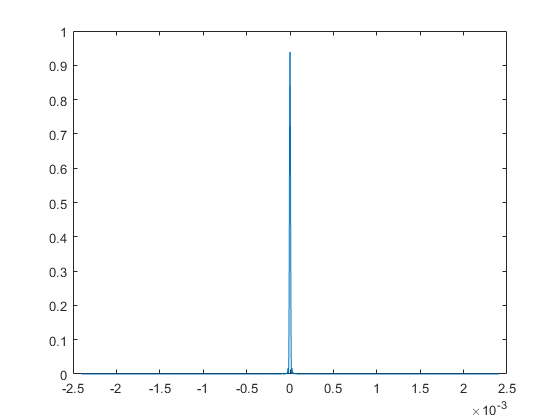

    
% 2) calculate the Airy disk pattern I_airy(r) for the array Xs, and compare it to I_wave(r);
    x=2*pi*Aperture_Radius/lambda*Xs./sqrt(Xs.^2+d^2);
    I=(2*besselj(1,x)./x).^2;
    
    figure(6)
    plot(Xs,I);

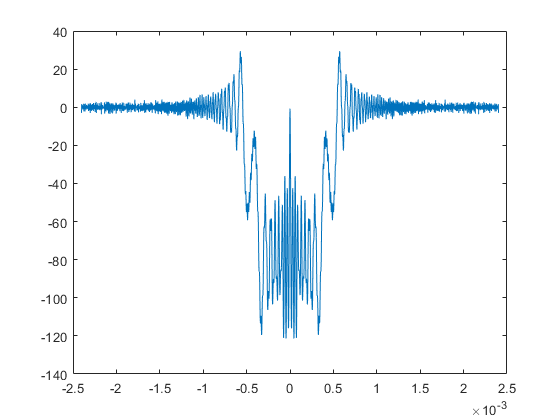

    figure(7)
    plot(Xs, A);


% 3) Create 2D arrays of x and y coordinates of the screen elements, analogues to XaM and YaM, see section 2 of the script;
    [XsM, YsM] = meshgrid(Xs,Xs); % Matrix XsM contains X coordinates of all screen elements;
                                  % Matrix YsM contains Y coordinates of all screen elements;


% 4) Calculate the intensity I_wave(r) for all elements on the screen, and plot it as a 2D image (analogue of the picture taken by camera);
    A_all = zeros([length(XsM) length(YsM)]);
    
    for x = 1:length(XsM)
        for y = 1:length(YsM)
            dSx = XsM(1,x);
            dSy = YsM(y,1);
            r_minus_r_a = sqrt((XaM - dSx).^2 + (YaM - dSy).^2 + d.^2);
            theta = acos(d./r_minus_r_a);
            K = -1i/(2*lambda).*(1+cos(theta));
            allAmps = imag(A0.*K.*exp(1i.*k.*abs(r_minus_r_a))./abs(r_minus_r_a).*dxs^2);
            allAmps(isinf(allAmps_x) | -isinf(allAmps_x)) = 0;
            A_all(x,y) = sum(sum(allAmps));    
        end
    end
    
    I_wave_all = A_all.^2;
    
    fprintf("A_all = ");
    disp(A_all);
    fprintf("I_wave_all = ");
    disp(I_wave_all);
    imagesc(I_wave_all); colormap("gray")

    
% 5) Calculate the total power of the simulated diffraction pattern. It should be equal to the power of the wave at the aperture.
    P_s = I_wave_all .* Screen_Area;
    
    fprintf("P_s = ");
    disp(P_s);
    
    
fprintf("------------------------------------------------");

## Section 6. Extracting diffraction pattern from an image

fprintf("\n\n\n")
fprintf("------------------------------------------------");
fprintf("------------------- SECTION 6 ------------------");

IMAGE=imread('Image4.bmp');
figure(3);
imshow(IMAGE);

% Use ZOOM IN and DATA CURSOR tools of the figure window to find the
% center of the diffraction pattern.

% To be free of these restrictions we will convert uint8 type into double
% type:

IMAGE_dbl=double(IMAGE);

% Now you can calculate baground, rescale image data, extract cross section
% through the center of the diffraction pattern and compare it with the
% simulation
G = P_a./sum(sum(P_s));

fprintf("------------------------------------------------");